%% ASEN5044 Assignment 1 Solutions
% Y. Shen
% 31 August 2018
%% Problem 3
% Part B
Ix = 500; % kg mˆ3
Iy = 750; % kg mˆ3
Iz = 1000; % kg mˆ3
p0 = 20; % rad/s
dt = 0.1;
A = [0 0 0; 0 0 p0*(Ix - Iz)/Iy; 0 p0*(Iy - Ix)/Iz 0];
B=[1/Ix,0,0;0,1/Iy,0;0,0,1/Iz]

B =     0.0020         0         0
         0    0.0013         0
         0         0    0.0010


C=[1,0,0;0,1,0;0,0,1]

C =      1     0     0
     0     1     0
     0     0     1



sys=ss(A,B,C,[])

sys =
 
  A = 
           x1      x2      x3
   x1       0       0       0
   x2       0       0  -13.33
   x3       0       5       0
 
  B = 
             u1        u2        u3
   x1     0.002         0         0
   x2         0  0.001333         0
   x3         0         0     0.001
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
 
Continuous-time state-space model.


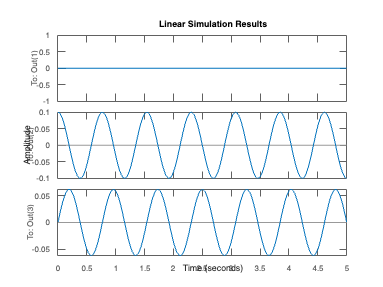

 x0 = [0; 0.1; 0]; % Initial conditions (rad/s)
 t = 0:0.01:5; % Times (s)
 x = zeros(3, length(t)); % States (rad/s)
lsim(sys,x,t,x0,'zoh')

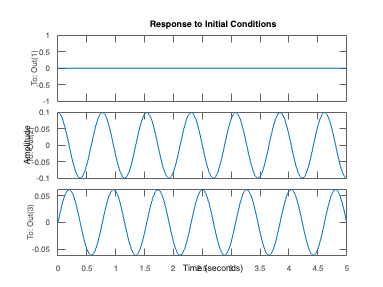


initial(sys,x0,5)

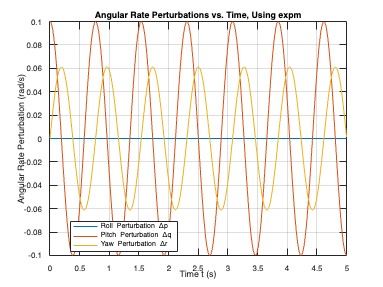

Phi = expm(A*dt);
%% Part C
t = 0:0.01:5; % Times (s)

x = zeros(3, length(t)); % States (rad/s)
for i = 1:length(t)
x(:, i) = expm(A*t(i))*x0;
end
figure;
plot(t, x);
xlabel('Time t (s)');
ylabel('Angular Rate Perturbation (rad/s)');
title('Angular Rate Perturbations vs. Time, Using expm');
legend('Roll Perturbation \Deltap', 'Pitch Perturbation \Deltaq', 'Yaw Perturbation \Deltar', 'location', 'best');
grid on;